# Homework 2

**Name**:

**Session** (ROB 599 or ROB 498): 

**Reading Assignment**: 

**YouTube Playlist**: [https://www.youtube.com/playlist?list=PLEYKx4BGriISagN3Ihc-9L6Cw44vtzTD9](https://www.youtube.com/playlist?list=PLEYKx4BGriISagN3Ihc-9L6Cw44vtzTD9) 

**Submission**: Export this file as a PDF and submit to Canvas. 

**The following Videos** are also requried to be submitted for this homework:

- "JointSpace"

- "TaskSpace_method1"

- "TaskSpace_method2"

- "ContactSim"

**Deadline**: 10/8/2025

- If you have any questions about the assignment or software, please use the Discussion function on Canvas to seek help!

- If your question was not addressed on Canvas, then reach out to GSI: Yulun Zhuang

- The live script for homework is still evolving, please check Canvas periodically to make sure you are working on the latest version

# Written Assignment

## Use LaTex for homework

Use LaTex syntax to anwer the written part of the assignment

Latex expressions can be brought up by pressing ctrl + shift + L in Windows or cmd + shift + L in Mac 

## Problem 1: Manipulability and Force Ellipsoids [2 pts]

1a) [1 pt] A manipulability ellipsoid chracterizes the end-effector's ability to generate velocity. It consists of the set of velocity vectors $\dot{x}$ that satisfies $\dot{x}^{\top}A^{-1}\dot{x}=1$. Derive the expression for matrix $A$.

#### 
$$Given \ \dot{x} = J \dot{q}\  and \ \dot{q}^\top \dot{q} = 1$
\[
\dot{x}^\top (J J^\top)^{-1} \dot{x}
= (J\dot{q})^\top (J J^\top)^{-1} (J\dot{q})
= \dot{q}^\top \dot{q}
= 1.
\]
Matching $\dot{x}^\top A^{-1}\dot{x}=1$ gives
\[
\\{A = J J^\top}
\]

$$


1b) [1 pt] A force ellipsoid chracterizes the end-effector's ability to generate force. It consists of the set of forces $f$ that satisfies $f^{\top}B^{-1}f=1$. Derive the expression for matrix $B$.

# 
$$\text{Given}
\\
\tau = J^\top f.

\\ Assume \ \tau^\top \tau = 1.


\\Then
\[
(J^\top f)^\top (J^\top f)
= f^\top J J^\top f
= 1.
\]

Comparing this with the definition $f^\top B^{-1} f = 1$, we obtain
\[
{B = (J J^\top)^{-1}}
\]
$$


## Problem 2: Inverse Velocity Kinematics [2 pts]

Denote the joint space variable $q$ and task space variable $p$, then a redundant robot is defined as: $q \in \mathbb{R}^n, p \in \mathbb{R}^m, m < n$. 

2a) [1pt] The jacobian matrix $J$ relates joint velocity $\dot{q}$ to task space velocity $V=J\dot{q}$. What is the expression of the Moore-Penrose Pseudoinverse matrix $J^{\dagger}$?


$$\text{Given} $V = J \dot{q}$, where\ $J \in $R^{m \times n}$ and $m < n$. 

Then
\[
\dot{q} = J^{\dagger} V,
\]
where
\[
J^{\dagger} = J^\top (J J^\top)^{-1}.
\]
$$


2b) [1pt] What is special about the solution $\dot{q}$ given by this specific matrix $J^{\dagger}$?


$$
\[
\dot{q} = J^{\dagger} V
\]
is the \text{minimum-norm solution}\ among all joint velocities satisfying
\[
J\dot{q} = V,
\]
it has the smallest Euclidean norm
\[
\|\dot{q}\|_2 = \min.
\]$$


## Problem 3: Least-Square Problem [4 pts]

Least-square problem is a type of unconstrained optimization problem with an objective which is a sum of squares


$$\text{minimize} \quad f_{0}(x) = \|Ax - b\|_{2}^{2} 
= \sum_{i=1}^{k} \left(a_{i}^{T}x - b_{i}\right)^{2}.
$$


3a) [2 pts] Suppose we have $A\in \mathbb{R}^{m\times n}, m > n$ as in a typical regression problem. What is the analytical solution of the least-square problem?


$${x^\ast = (A^\top A)^{-1}A^\top b}.$$


3b) [2 pts] We can solve numerical IK problems as nonlinear least-square problems in the following form:


$$\text{minimize} \quad f(q)
= e(q)^\top e(q),$$


where $e(q) = FK(q) - P_d$ and $P_d
$ is the desired end-effector pose. 

Derive the gradient of the objective $f(q)$ with respect to decision variable $q$


$$
f(q)=e(q)^\top e(q),\quad \mathrm{d}f = 2 e^\top \mathrm{d}e,
\quad \mathrm{d}e = J\,\mathrm{d}q
\Rightarrow
{\nabla_q f(q)=2\,J(q)^\top e(q)}.
\]$$


## Problem 4: Task-Space Control [6 pts]

The manipulator EoM is: $M\ddot{q} + h = \tau$. Assume that the Jacobian matrix $J$ is invertable.

4a) [2 pts] Derive the task-space inertia matrix $\Lambda$ as a function of $M$ and $J$ from the perspective of conservation of kinetic energy.


$${\Lambda=(J M^{-1} J^\top)^{-1}}.$$


4b) [2 pts] Given desired task-space position $p_d$, velocity $\dot{p}_d$ and acceleration $\ddot{p}_d$, what is the task-space dynamics that follows the mass-spring-damper sytem?

Note: Assume taks-space inertia $\Lambda$, stiffness $K_p$ and damping $K_d$


$${\ddot p_{\rm des} = \ddot p_d
- \Lambda^{-1}\!\big(K_d(\dot p-\dot p_d)+K_p(p-p_d)\big)}.$$


4c) [2 pts] How to realize TSC by solving a system of linear equations? Derive the linear system in the standard form of $Ax=b$


$$$$
\left[
\begin{array}{cc}
M & -J^{T} \\
J & 0
\end{array}
\right]
\left[
\begin{array}{c}
\ddot{q} \\
F
\end{array}
\right]
=
\left[
\begin{array}{c}
-h \\
\ddot{p}_{\mathrm{des}} - \dot{J}\dot{q}
\end{array}
\right]
$$







$\tau = J^\top F$$


# Coding Assignment

## Codebase Structure & Setup

Execute the `setup.m` script **separately** to add paths of `spatical_v2` and check installation status of CasADi.

clear; close all force;
run ../codeBase/setup.m
p.robot = model_inverted_leg();
p.linkLength = p.robot.linkLength';

Setup Success!


p.robot_viz = model_inverted_leg_viz();

## Assignment 1: Task Space Control [5 pts]

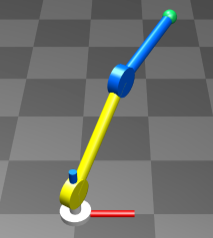

1) [2 pts] Derive the expression of  using the  function 

regenerate_symbolic = true;

if regenerate_symbolic == true

% forward kinematics
syms q dq l [3,1] real;

T01 = [rot(q1, 'z'), [0, 0, 0]';
       zeros(1, 3), 1]

T12 = [rot(q2, 'y'), [0, 0, l1]';
       zeros(1, 3), 1]

T23 = [rot(q3, 'y'), [0, 0, l2]';
       zeros(1, 3), 1]

T34 = [eye(3), [0, 0, l3]';
       zeros(1, 3), 1]

T_ee = T01 * T12 * T23 * T34;
pos_ee_htm = simplify(T_ee(1:3, 4));
J_ee = simplify(jacobian(pos_ee_htm, q));
vel_ee = J_ee * dq;

Hint: the time derivative of Jacobian: $\dot{J}=\frac{\partial J}{\partial q}\dot{q}$ is a 3-dimensional tensor, the product $\dot{J}\dot{q}$ is a 2-dimensional matrix

% Compute dJdq_ee for the end-effector
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS

dJdq_ee = sym(zeros(size(J_ee))); 

for i = 1:length(q)
    dJdq_ee = dJdq_ee + diff(J_ee, q(i)) * dq(i);
end

dJdq_ee = simplify(dJdq_ee);

% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% generate kinematics functions
matlabFunction(pos_ee_htm, 'File', 'fcn_pos_ee.m', 'Vars', {q, l});
matlabFunction(J_ee, 'File', 'fcn_J_ee.m', 'Vars', {q, l});
matlabFunction(vel_ee, 'File', 'fcn_vel_ee.m', 'Vars', {q, dq, l});
matlabFunction(dJdq_ee, 'File', 'fcn_dJdq_ee.m', 'Vars', {q, dq, l});

end

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T34 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

2) [3 pts] The main tasks of this assignment is to implement 2 controllers in the **Function to be implemented **section below:

- JointSpace_controller

- TaskSpace_controller

Generate animation and plots to get a qualitative/quantitative comparison between two controllers

FLAG_controller = 'JointSpace';
[tout, Xout, XDesout] = run_controller(FLAG_controller, p);



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

fprintf('Simulation complete, use showmotion to animate the robot!')

Simulation complete, use showmotion to animate the robot!

Please make a recording of your animation and submit with the videos named:

- "JointSpace"

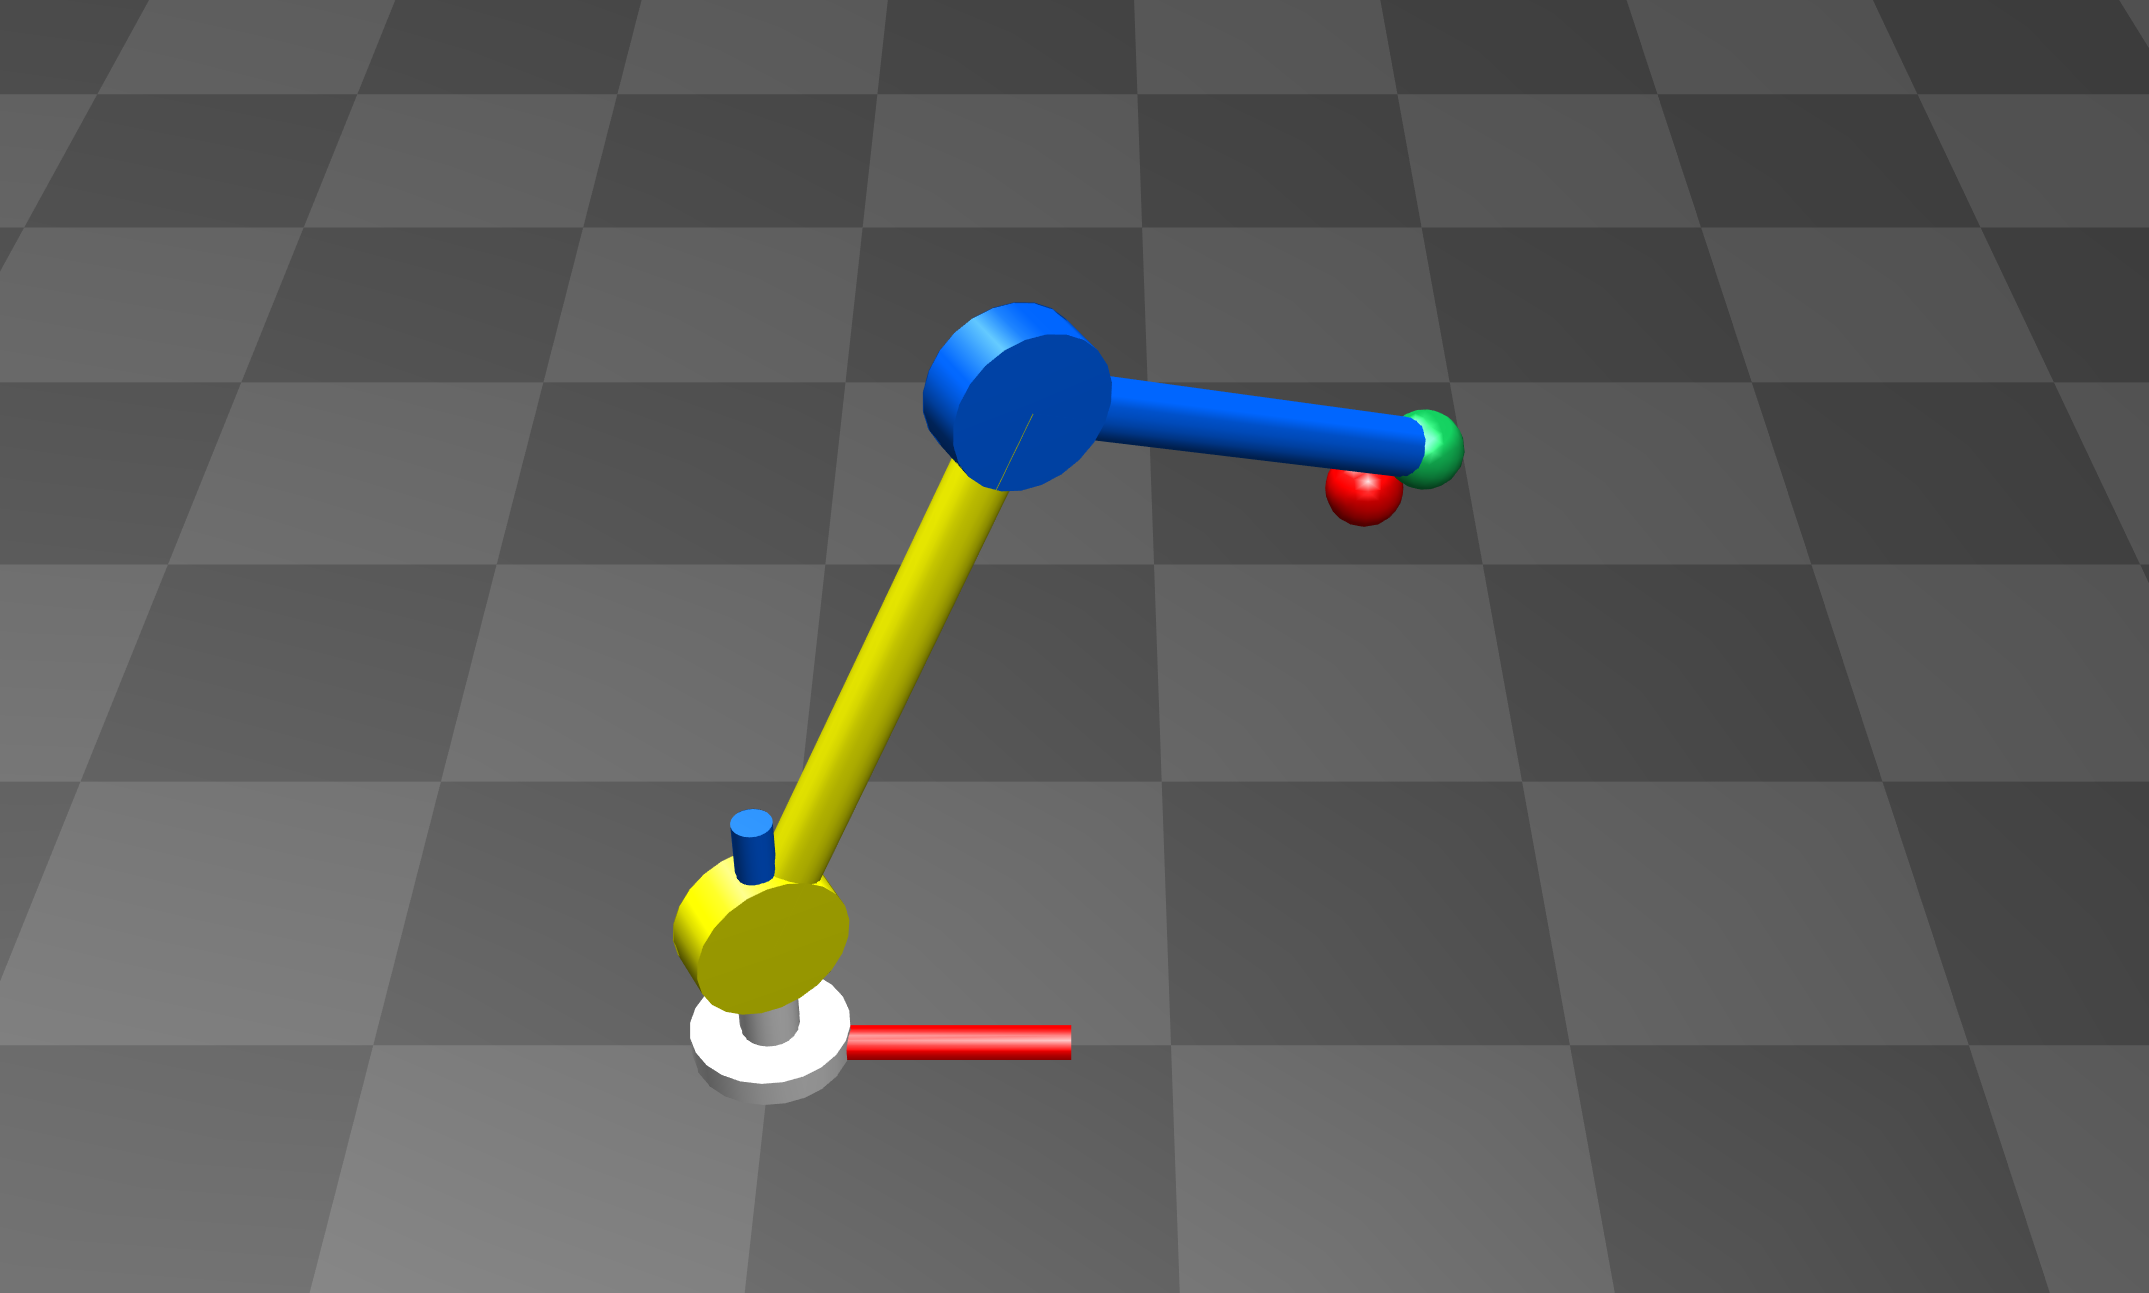

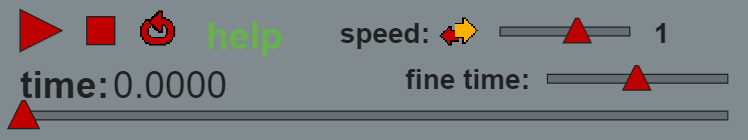

% Animation
t_viz = tout;
q_viz = [Xout(:,1:3), XDesout(:,1:3)]';
% copy the following line of code to the command window to animate
close all force;
showmotion(p.robot_viz,t_viz,q_viz);

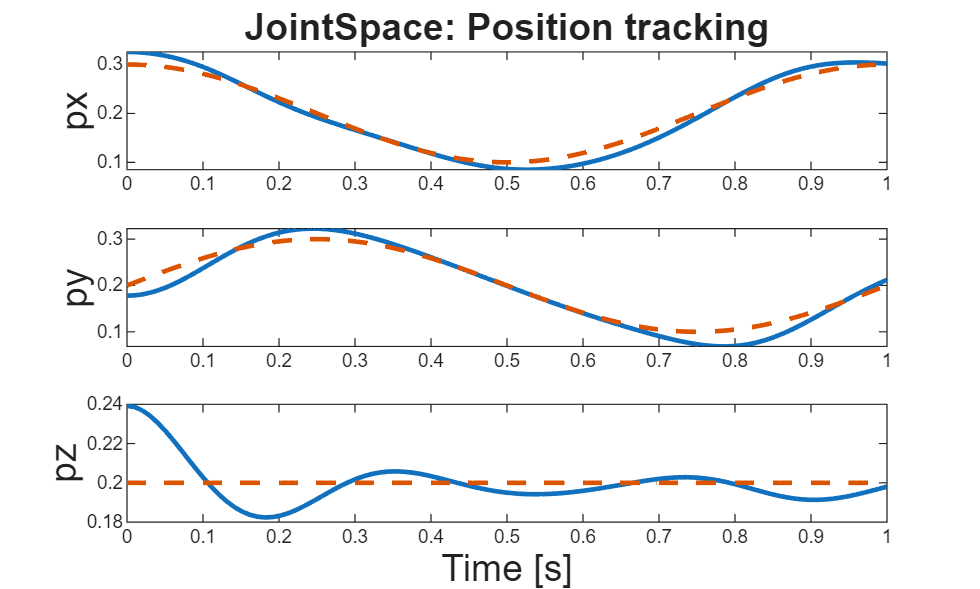

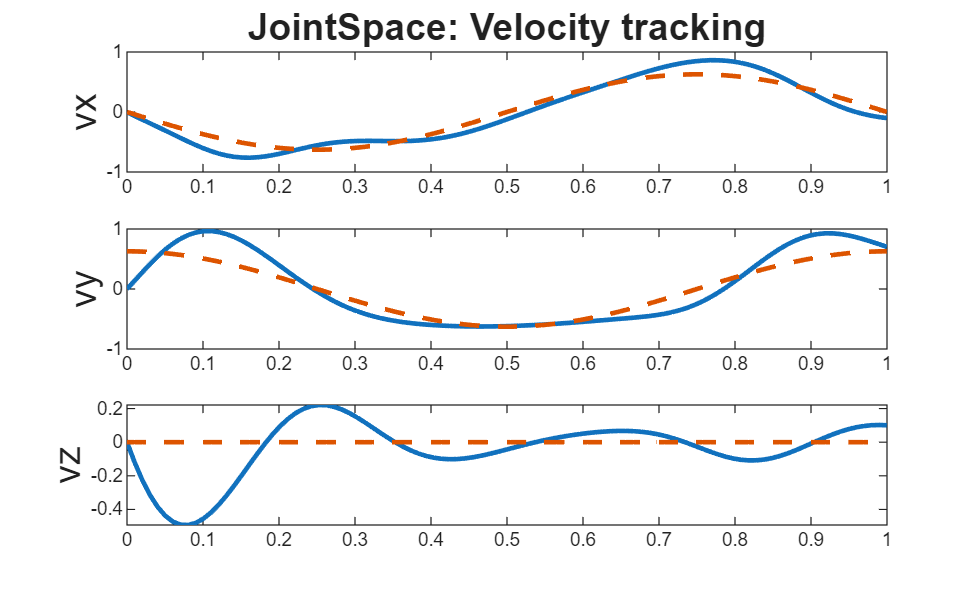

% Plots
makePlots_assignment1(tout, Xout, p, FLAG_controller)
FLAG_controller = 'TaskSpace';
[tout, Xout, XDesout] = run_controller(FLAG_controller, p);

fprintf('Simulation complete, use showmotion to animate the robot!')

sol =    40.4704
   14.5912
   27.9594
   -1.4894
    3.6342
   -3.7618


tau =     1.4487
    1.4655
    0.8099


sol =    40.8447
   14.9401
   21.5198
   -1.2615
    3.8039
   -3.3286


tau =     1.4628
    1.3503
    0.6802


sol =    40.0335
   15.4047
   14.1157
   -0.9911
    3.8809
   -2.8427


tau =     1.4371
    1.2153
    0.5355


sol =    38.0803
   15.7944
    6.2132
   -0.7173
    3.8571
   -2.3098


tau =     1.3751
    1.0557
    0.3817


sol =    35.0632
   15.8825
   -1.6565
   -0.4803
    3.7244
   -1.7327


tau =     1.2815
    0.8657
    0.2250


sol =    31.1011
   15.4499
   -8.9536
   -0.3142
    3.4755
   -1.1132


tau =     1.1615
    0.6407
    0.0717


sol =    26.3586
   14.3233
  -15.1803
   -0.2409
    3.1063
   -0.4548


tau =     1.0206
    0.3790
   -0.0722


sol =    21.0458
   12.4058
  -19.9231
   -0.2679
    2.6168
    0.2343


tau =     0.8640
    0.0835
   -0.2010


sol =    15.4100
    9.6916
  -22.8852
   -0.3884
    2.0131
    0.9394


tau =     0.6969
   -0.2380
   -0.3097


sol =     9.7182
    6.2656
  -23.9060
   -0.5846
    1.3077
    1.6384


tau =     0.5239
   -0.5738
   -0.3943


sol =     4.2339
    2.2871
  -22.9688
   -0.8323
    0.5195
    2.3045


tau =     0.3496
   -0.9092
   -0.4520


sol =    -0.8083
   -2.0375
  -20.1937
   -1.1065
   -0.3274
    2.9098


tau =     0.1784
   -1.2291
   -0.4814


sol =    -5.2238
   -6.4852
  -15.8191
   -1.3847
   -1.2055
    3.4296


tau =     0.0146
   -1.5199
   -0.4831


sol =    -8.8909
  -10.8433
  -10.1734
   -1.6499
   -2.0859
    3.8460


tau =    -0.1376
   -1.7712
   -0.4592


sol =   -11.7538
  -14.9280
   -3.6433
   -1.8899
   -2.9403
    4.1496


tau =    -0.2742
   -1.9761
   -0.4135


sol =   -13.8170
  -18.5916
    3.3588
   -2.0970
   -3.7421
    4.3396


tau =    -0.3919
   -2.1318
   -0.3509


sol =   -15.1324
  -21.7232
   10.4230
   -2.2658
   -4.4667
    4.4221


tau =    -0.4884
   -2.2381
   -0.2768


sol =   -15.7849
  -24.2430
   17.1651
   -2.3921
   -5.0921
    4.4077


tau =    -0.5623
   -2.2971
   -0.1967


sol =   -15.8770
  -26.0969
   23.2455
   -2.4719
   -5.5991
    4.3096


tau =    -0.6134
   -2.3118
   -0.1161


sol =   -15.5169
  -27.2533
   28.3845
   -2.5017
   -5.9718
    4.1418


tau =    -0.6428
   -2.2861
   -0.0395


sol =   -14.8091
  -27.7015
   32.3744
   -2.4790
   -6.1991
    3.9178


tau =    -0.6523
   -2.2237
    0.0292


sol =   -13.8486
  -27.4536
   35.0883
   -2.4032
   -6.2756
    3.6506


tau =    -0.6444
   -2.1286
    0.0875


sol =   -12.7185
  -26.5457
   36.4839
   -2.2765
   -6.2030
    3.3520


tau =    -0.6222
   -2.0052
    0.1335


sol =   -11.4886
  -25.0388
   36.6014
   -2.1040
   -5.9904
    3.0327


tau =    -0.5890
   -1.8580
    0.1668


sol =   -10.2171
  -23.0166
   35.5537
   -1.8933
   -5.6542
    2.7021


tau =    -0.5481
   -1.6919
    0.1877


sol = 6×1
   -8.9514
  -20.5807
   33.5104
   -1.6539
   -5.2164
    2.3684


tau = 3×1
   -0.5024
   -1.5121
    0.1973


sol = 6×1
   -7.7304
  -17.8437
   30.6771
   -1.3962
   -4.7025
    2.0384


tau = 3×1
   -0.4550
   -1.3239
    0.1971


sol = 6×1
   -6.5863
  -14.9208
   27.2735
   -1.1301
   -4.1395
    1.7178


tau = 3×1
   -0.4083
   -1.1326
    0.1890


sol = 6×1
   -5.5463
  -11.9232
   23.5141
   -0.8645
   -3.5529
    1.4111


tau = 3×1
   -0.3641
   -0.9431
    0.1749


sol = 6×1
   -4.6342
   -8.9515
   19.5933
   -0.6065
   -2.9658
    1.1219


tau = 3×1
   -0.3242
   -0.7599
    0.1563


sol = 6×1
   -3.8709
   -6.0927
   15.6756
   -0.3616
   -2.3975
    0.8534


tau = 3×1
   -0.2896
   -0.5868
    0.1348


sol = 6×1
   -3.2753
   -3.4182
   11.8918
   -0.1333
   -1.8630
    0.6082


tau = 3×1
   -0.2607
   -0.4272
    0.1114


sol = 6×1
   -2.8647
   -0.9843
    8.3391
    0.0761
   -1.3735
    0.3887


tau = 3×1
   -0.2380
   -0.2835
    0.0872


sol = 6×1
   -2.6538
    1.1670
    5.0845
    0.2656
   -0.9368
    0.1975


tau = 3×1
   -0.2213
   -0.1580
    0.0626


sol = 6×1
   -2.6552
    3.0064
    2.1691
    0.4349
   -0.5577
    0.0370


tau = 3×1
   -0.2102
   -0.0521
    0.0379


sol = 6×1
   -2.8780
    4.5158
   -0.3870
    0.5841
   -0.2386
   -0.0902


tau = 3×1
   -0.2041
    0.0333
    0.0135


sol = 6×1
   -3.3275
    5.6866
   -2.5797
    0.7139
    0.0199
   -0.1818


tau = 3×1
   -0.2023
    0.0977
   -0.0108


sol = 6×1
   -4.0044
    6.5196
   -4.4180
    0.8250
    0.2185
   -0.2355


tau = 3×1
   -0.2042
    0.1411
   -0.0348


sol = 6×1
   -4.9045
    7.0237
   -5.9199
    0.9184
    0.3594
   -0.2496


tau = 3×1
   -0.2089
    0.1640
   -0.0587


sol = 6×1
   -6.0182
    7.2165
   -7.1112
    0.9953
    0.4458
   -0.2233


tau = 3×1
   -0.2157
    0.1674
   -0.0823


sol = 6×1
   -7.3312
    7.1237
   -8.0236
    1.0569
    0.4818
   -0.1567


tau = 3×1
   -0.2238
    0.1529
   -0.1059


sol = 6×1
   -8.8247
    6.7790
   -8.6937
    1.1047
    0.4728
   -0.0513


tau = 3×1
   -0.2325
    0.1225
   -0.1292


sol = 6×1
  -10.4764
    6.2241
   -9.1622
    1.1404
    0.4250
    0.0898


tau = 3×1
   -0.2414
    0.0790
   -0.1522


sol = 6×1
  -12.2618
    5.5078
   -9.4734
    1.1658
    0.3457
    0.2614


tau = 3×1
   -0.2499
    0.0254
   -0.1748


sol = 6×1
  -14.1549
    4.6853
   -9.6737
    1.1830
    0.2430
    0.4566


tau = 3×1
   -0.2577
   -0.0347
   -0.1965


sol = 6×1
  -16.1294
    3.8166
   -9.8110
    1.1942
    0.1258
    0.6660


tau = 3×1
   -0.2646
   -0.0974
   -0.2173


sol = 6×1
  -18.1588
    2.9653
   -9.9332
    1.2023
    0.0034
    0.8783


tau = 3×1
   -0.2704
   -0.1584
   -0.2365


sol = 6×1
  -20.2166
    2.1968
  -10.0867
    1.2105
   -0.1143
    1.0802


tau = 3×1
   -0.2751
   -0.2133
   -0.2539


sol = 6×1
  -22.2744
    1.5766
  -10.3141
    1.2224
   -0.2175
    1.2562


tau = 3×1
   -0.2789
   -0.2576
   -0.2687


sol = 6×1
  -24.3004
    1.1683
  -10.6527
    1.2428
   -0.2960
    1.3892


tau = 3×1
   -0.2821
   -0.2867
   -0.2805


sol = 6×1
  -26.2558
    1.0323
  -11.1327
    1.2769
   -0.3402
    1.4608


tau = 3×1
   -0.2848
   -0.2961
   -0.2884


sol = 6×1
  -28.0913
    1.2235
  -11.7747
    1.3311
   -0.3407
    1.4514


tau = 3×1
   -0.2874
   -0.2816
   -0.2917


sol = 6×1
  -29.7417
    1.7888
  -12.5885
    1.4124
   -0.2885
    1.3413


tau = 3×1
   -0.2900
   -0.2393
   -0.2894


sol = 6×1
  -31.1223
    2.7648
  -13.5722
    1.5279
   -0.1760
    1.1118


tau = 3×1
   -0.2928
   -0.1656
   -0.2809


sol = 6×1
  -32.1243
    4.1730
  -14.7106
    1.6846
    0.0031
    0.7469


tau = 3×1
   -0.2953
   -0.0583
   -0.2652


sol = 6×1
  -32.6143
    6.0154
  -15.9759
    1.8875
    0.2526
    0.2361


tau = 3×1
   -0.2968
    0.0837
   -0.2418


sol = 6×1
  -32.4361
    8.2684
  -17.3282
    2.1382
    0.5731
   -0.4226


tau = 3×1
   -0.2959
    0.2596
   -0.2105


sol = 6×1
  -31.4197
   10.8759
  -18.7169
    2.4331
    0.9608
   -1.2189


tau = 3×1
   -0.2908
    0.4657
   -0.1716


sol = 6×1
  -29.3975
   13.7439
  -20.0833
    2.7613
    1.4060
   -2.1267


tau = 3×1
   -0.2788
    0.6952
   -0.1265


sol = 6×1
  -26.2292
   16.7373
  -21.3631
    3.1035
    1.8929
   -3.1016


tau = 3×1
   -0.2573
    0.9375
   -0.0770


sol = 6×1
  -21.8353
   19.6818
  -22.4906
    3.4325
    2.3987
   -4.0808


tau = 3×1
   -0.2237
    1.1782
   -0.0263


sol = 6×1
  -16.2323
   22.3730
  -23.4019
    3.7150
    2.8943
   -4.9875


tau = 3×1
   -0.1765
    1.4002
    0.0218


sol = 6×1
   -9.5642
   24.5951
  -24.0395
    3.9168
    3.3463
   -5.7382


tau = 3×1
   -0.1158
    1.5848
    0.0630


sol = 6×1
   -2.1167
   26.1480
  -24.3569
    4.0083
    3.7200
   -6.2557


tau = 3×1
   -0.0439
    1.7146
    0.0933


sol = 6×1
    5.6968
   26.8784
  -24.3234
    3.9706
    3.9842
   -6.4828


tau = 3×1
    0.0347
    1.7761
    0.1095


sol = 6×1
   13.3810
   26.7089
  -23.9286
    3.7996
    4.1169
   -6.3945


tau = 3×1
    0.1138
    1.7627
    0.1098


sol = 6×1
   20.4321
   25.6554
  -23.1858
    3.5070
    4.1101
   -6.0044


tau = 3×1
    0.1867
    1.6760
    0.0946


sol = 6×1
   26.4206
   23.8263
  -22.1322
    3.1178
    3.9724
   -5.3620


tau = 3×1
    0.2479
    1.5259
    0.0662


sol = 6×1
   31.0573
   21.4021
  -20.8256
    2.6651
    3.7273
   -4.5424


tau = 3×1
    0.2941
    1.3285
    0.0283


sol = 6×1
   34.2256
   18.6011
  -19.3367
    2.1837
    3.4086
   -3.6305


tau = 3×1
    0.3245
    1.1027
   -0.0148


sol = 6×1
   35.9720
   15.6420
  -17.7394
    1.7050
    3.0529
   -2.7053


tau = 3×1
    0.3406
    0.8672
   -0.0586


sol = 6×1
   36.4659
   12.7135
  -16.1024
    1.2529
    2.6934
   -1.8297


tau = 3×1
    0.3456
    0.6372
   -0.0997


sol = 6×1
   35.9454
    9.9572
  -14.4818
    0.8430
    2.3548
   -1.0453


tau = 3×1
    0.3431
    0.4239
   -0.1358


sol = 6×1
   34.6675
    7.4631
  -12.9183
    0.4828
    2.0526
   -0.3735


tau = 3×1
    0.3364
    0.2337
   -0.1655


sol = 6×1
   32.8715
    5.2761
  -11.4375
    0.1735
    1.7937
    0.1805


tau = 3×1
    0.3282
    0.0693
   -0.1883


sol = 6×1
   30.7599
    3.4061
  -10.0518
   -0.0879
    1.5781
    0.6225


tau = 3×1
    0.3204
   -0.0695
   -0.2045


sol = 6×1
   28.4916
    1.8392
   -8.7635
   -0.3069
    1.4021
    0.9645


tau = 3×1
    0.3139
   -0.1844
   -0.2146


sol = 6×1
   26.1838
    0.5479
   -7.5681
   -0.4900
    1.2596
    1.2210


tau = 3×1
    0.3092
   -0.2782
   -0.2196


sol = 6×1
   23.9185
   -0.5023
   -6.4566
   -0.6439
    1.1440
    1.4071


tau = 3×1
    0.3064
   -0.3540
   -0.2201


sol = 6×1
   21.7499
   -1.3475
   -5.4180
   -0.7745
    1.0489
    1.5365


tau = 3×1
    0.3051
   -0.4147
   -0.2169


sol = 6×1
   19.7113
   -2.0227
   -4.4400
   -0.8873
    0.9686
    1.6214


tau = 3×1
    0.3051
   -0.4632
   -0.2108


sol = 6×1
   17.8206
   -2.5603
   -3.5107
   -0.9869
    0.8985
    1.6720


tau = 3×1
    0.3060
   -0.5018
   -0.2024


sol = 6×1
   16.0856
   -2.9890
   -2.6185
   -1.0769
    0.8348
    1.6968


tau = 3×1
    0.3075
   -0.5328
   -0.1922


sol = 6×1
   14.5067
   -3.3339
   -1.7533
   -1.1605
    0.7745
    1.7026


tau = 3×1
    0.3093
   -0.5578
   -0.1805


sol = 6×1
   13.0793
   -3.6163
   -0.9062
   -1.2401
    0.7153
    1.6948


tau = 3×1
    0.3110
   -0.5784
   -0.1678


sol = 6×1
   11.7962
   -3.8542
   -0.0696
   -1.3174
    0.6556
    1.6778


tau = 3×1
    0.3126
   -0.5958
   -0.1544


sol = 6×1
   10.6480
   -4.0627
    0.7624
   -1.3939
    0.5941
    1.6548


tau = 3×1
    0.3139
   -0.6109
   -0.1404


sol = 6×1
    9.6244
   -4.2539
    1.5944
   -1.4707
    0.5297
    1.6284


tau = 3×1
    0.3148
   -0.6246
   -0.1261


sol = 6×1
    8.7144
   -4.4375
    2.4296
   -1.5483
    0.4618
    1.6006


tau = 3×1
    0.3151
   -0.6376
   -0.1116


sol = 6×1
    7.9073
   -4.6210
    3.2696
   -1.6272
    0.3897
    1.5727


tau = 3×1
    0.3149
   -0.6502
   -0.0972


sol = 6×1
    7.1923
   -4.8100
    4.1151
   -1.7074
    0.3130
    1.5459


tau = 3×1
    0.3141
   -0.6630
   -0.0828


sol = 6×1
    6.5589
   -5.0085
    4.9657
   -1.7889
    0.2314
    1.5207


tau = 3×1
    0.3125
   -0.6761
   -0.0686


sol = 6×1
    5.9973
   -5.2191
    5.8198
   -1.8714
    0.1445
    1.4978


tau = 3×1
    0.3102
   -0.6898
   -0.0548


sol = 6×1
    5.4980
   -5.4430
    6.6751
   -1.9543
    0.0522
    1.4774


tau = 3×1
    0.3071
   -0.7042
   -0.0413


sol = 6×1
    5.0524
   -5.6804
    7.5286
   -2.0372
   -0.0456
    1.4596


tau = 3×1
    0.3030
   -0.7193
   -0.0283


sol = 6×1
    4.6525
   -5.9307
    8.3766
   -2.1192
   -0.1492
    1.4444


tau = 3×1
    0.2980
   -0.7351
   -0.0158


sol = 6×1
    4.2907
   -6.1922
    9.2148
   -2.1995
   -0.2583
    1.4318


tau = 3×1
    0.2919
   -0.7515
   -0.0038


sol = 6×1
    3.9606
   -6.4631
   10.0386
   -2.2770
   -0.3728
    1.4217


tau = 3×1
    0.2846
   -0.7685
    0.0075


sol = 6×1
    3.6560
   -6.7406
   10.8431
   -2.3507
   -0.4925
    1.4138


tau = 3×1
    0.2761
   -0.7859
    0.0182


sol = 6×1
    3.3718
   -7.0218
   11.6230
   -2.4196
   -0.6170
    1.4080


tau = 3×1
    0.2663
   -0.8036
    0.0283


Simulation complete, use showmotion to animate the robot!

Please make a recording of your animation and submit with the videos named:

- "TaskSpace_method1"

- "TaskSpace_method2"

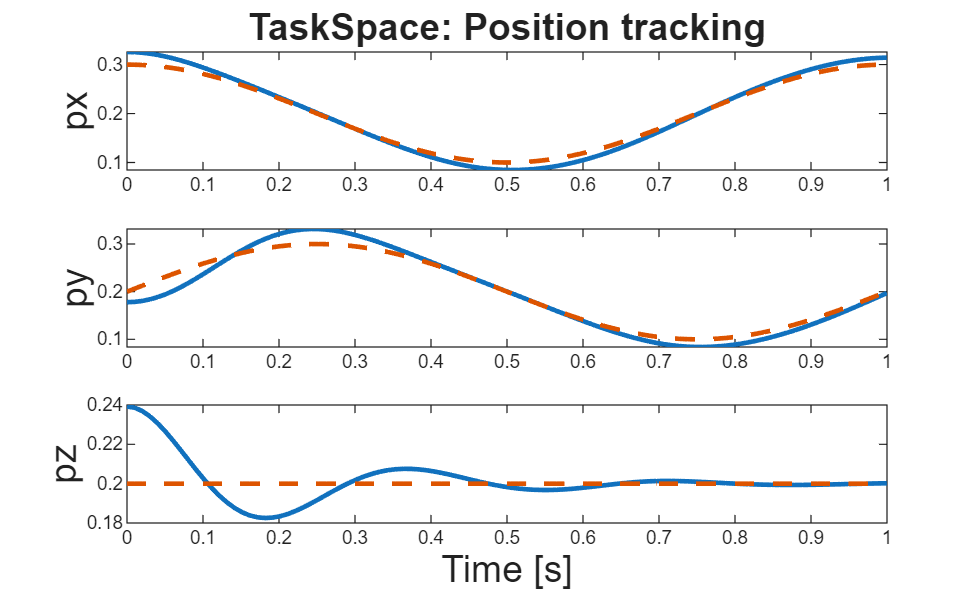

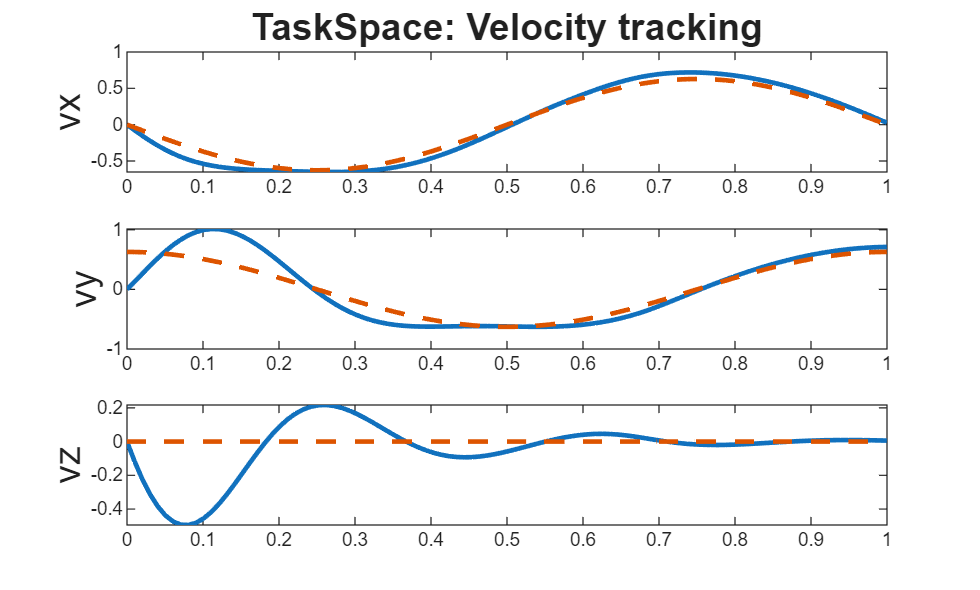

% Animation
t_viz = tout;
q_viz = [Xout(:,1:3), XDesout(:,1:3)]';
% copy the following line of code to the command window to animate
% close all force;
% showmotion(p.robot_viz,t_viz,q_viz);

% Plots
makePlots_assignment1(tout, Xout, p, FLAG_controller)

#### Function to be implemented

function [tau, qDes] = JointSpace_controller(rs, rsDes, qGuess, p)
q = rs.q;
dq = rs.dq;
J = rs.J_ee;
posDes = rsDes.pos;
velDes = rsDes.vel;
M = rs.M;
bias = rs.bias;

Kp = diag(300 * [1,1,1]);
Kd = diag(10 * [1,1,1]);

% Perform IK to get the desired joint angle and velocity
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% - Define the residual function e = pos - posDes
residual = @(qVar) fcn_pos_ee(qVar, p.linkLength) - posDes;
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% - use lsqnonlin function to solve for qDes
qDes = lsqnonlin(residual, qGuess);
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% - solve for dqDes using velocity IK
dqDes = pinv(fcn_J_ee(qDes, p.linkLength)) * velDes;
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ddqDes = Kp * (qDes - q) + Kd * (dqDes - dq);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% - define tau to achieve joint space controller that uses partial feedback
% linearization (PFL)
tau = M * ddqDes + bias;
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end


Implement the Task-Space controller using 2 methods:

- Projecting dynamics to the task space and get the task-space inertia matrix and bias term

- Solving the TSC problem as a system of linear equations

function tau = TaskSpace_controller(rs, rsDes, p)
M = rs.M;
bias = rs.bias;
J = rs.J_ee;
dJdq = rs.dJdq_ee;
Jinv = pinv(J);
Lambda = Jinv' * M * Jinv;

Kp = diag(300 * [1,1,1]);
Kd = diag(10 * [1,1,1]);

dvDes =  Kp * (rsDes.pos - rs.pos) + Kd * (rsDes.vel - rs.vel);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% Method 1: project dynamics to the task space
% - Calculate task space bias term mu
% - Perform TSC by defining joint torque tau to achieve partial feedback
% linearization (PFL)
mu = inv(J / M * J') * ( J * (M \ bias) - dJdq );
tau = J' * ( inv(J / M * J') * dvDes + mu );

% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE STARTS
% Method 2: solve TSC as a system of linear equations
n = size(M,1);  
m = size(J,1);  
A = [ M,       -J';
      J,  zeros(m, m) ];
b = [-bias;
     dvDes - dJdq * rs.dq];
sol = A \ b;
tau = J' * sol(n+1:n+m);
% YOUR CODE ENDS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

## Assignment 2: Contact Simulation [6 pts]

We are going to simulate the scenario where the robot falls due to gravity, hit the ground and bounce back.

Specifically, we will implement the functions ***impact_event*** and ***impact_map*** in the **Function to be implemented **section below:

tDuration = 3;
tstart = 0;
q0 = [-1 0.2 0.5]';
dq0 = [5 0 1]';
X0 = [q0; dq0];

[tout, Xout, Uout] = deal([]);

for ii = 1:5
tau = zeros(3,1);

opts = odeset('Events',@(t,X)impact_event(t,X,p));
[t, X, te] = ode45(@(t,X)dynamics(t, X, tau, p), [tstart, tDuration], X0, opts);

% impact map
tstart = te;
Xpre = X(end,:)';
X0 = impact_map(Xpre,p);

% logging
tout = [tout; t(2:end)];
Xout = [Xout; X(2:end,:)];
end

vc_new =    -0.5440
    0.2811
    0.9606


vc_new =    -0.5094
   -0.0727
    0.6472


vc_new =     0.1172
   -0.4809
    0.4201


vc_new =     1.3777
   -0.5683
    0.3356


vc_new =    -0.7982
    0.5095
    0.4312



fprintf('Simulation complete, use showmotion to animate the robot!')

Simulation complete, use showmotion to animate the robot!

#### Animation

Please make a recording of your animation and submit with the videos named:

- "ContactSim"

t_ = tout;
q_ = Xout(:,1:3)';
% copy the following line of code to the command window to animate
% close all force;
% showmotion(p.robot,t_,q_)

#### Plots

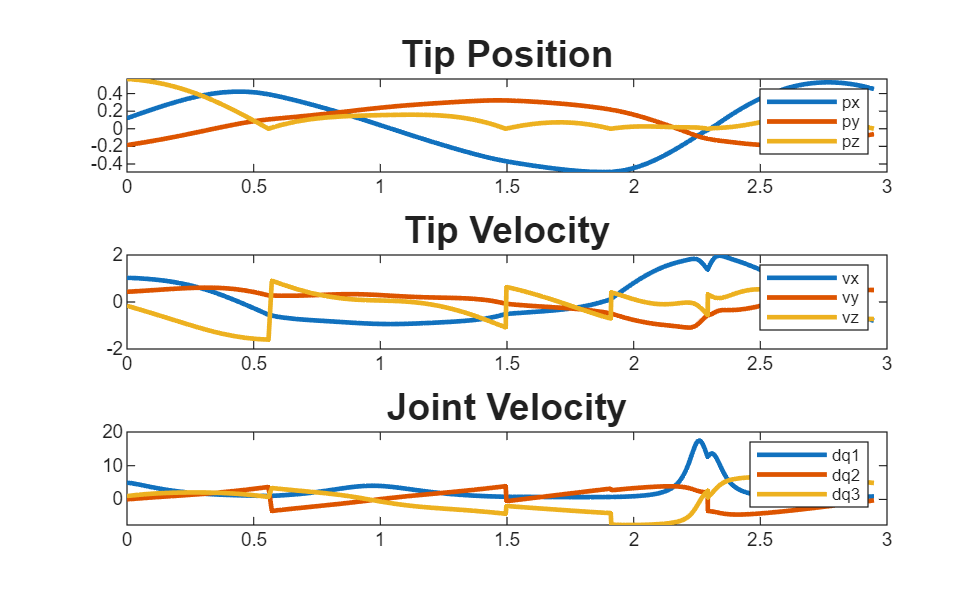

N = length(t_);
qLog  = Xout(:,1:3);
dqLog = Xout(:,4:6);
for k = 1:N
    qk  = qLog(k,:)';
    dqk = dqLog(k,:)';
    posAct(:,k) = fcn_pos_ee(qk,  p.linkLength);
    velAct(:,k) = fcn_vel_ee(qk,dqk,p.linkLength);
end

figure
subplot(3,1,1)
plot(t_,posAct,'LineWidth',2)
legend('px','py','pz')
title('Tip Position','FontSize',16)

subplot(3,1,2)
plot(t_,velAct,'LineWidth',2)
legend('vx','vy','vz')
title('Tip Velocity','FontSize',16)
subplot(3,1,3)
plot(t_,dqLog,'LineWidth',2)
legend('dq1','dq2','dq3')
title('Joint Velocity','FontSize',16)

#### Functions to be implemented

function [value, isterminal, direction] = impact_event(t, X, p)
    q = X(1:3);
    linkLength = p.linkLength;

    pos = fcn_pos_ee(q,linkLength);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    % - define value as the signed distance function
    value = pos(3);
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    isterminal = 1;
    direction = -1;
end

function [Xp, F] = impact_map(X, p)
    q = X(1:3);
    dq = X(4:6);
    linkLength = p.linkLength;
    eta = 0.6;          % coefficient of restitution

    Jc = fcn_J_ee(q, linkLength);
    M = HandC(p.robot, q, dq);

    % M * (dq_new - dq_old) = Jc' * F;
    % Jc * dq_new = vel_new
    dq_old = dq;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    % - Define the post-impact EE velocity
    % vel_new = Matrix(eta) * Jc * dq_old
    % think about how the Matrix should be defined if:
    % the vx = eta*vx, vy = eta*vy, vz = -eta*vz
    vc_new = diag([1, 1, -eta]) * Jc * dq_old
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    % - Formulate the linear system for the impact map
    Amat = [M, -Jc';
            Jc, zeros(3,3)];

    bvec = [M * dq_old;
            vc_new]; 

    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % YOUR CODE STARTS
    % - Solve the linear system to get dqnew_F
    dqnew_F = Amat \ bvec; 
    % YOUR CODE ENDS
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    dq_new = dqnew_F(1:3);
    F = dqnew_F(4:6);

    Xp = [q; dq_new];
end

## Helper Functions

function [tout, Xout, XDesout] = run_controller(ctrl_type, p)

% parameters
tstart = 0;
tDuration = 1;
dt_sim = 0.01;
MAX_ITER = floor(tDuration / dt_sim);

[tout, Xout, Uout, XDesout] = deal([]);

tend = dt_sim;
q0 = [0.5 0.5 1.5]';
dq0 = [0 0 0]';
X0 = [q0; dq0];
qDes = q0;
% simulate robot
for ii = 1:MAX_ITER

    rs = getRobotState(X0, p);
    
    rsDes = getRobotStateDes(tstart, p);

    % controllers
    if strcmp(ctrl_type, 'JointSpace')
        [tau, qDes] = JointSpace_controller(rs, rsDes, qDes, p);
    elseif strcmp(ctrl_type, 'TaskSpace')
        tau = TaskSpace_controller(rs, rsDes, p);
    end

    % simulation
    [t, X] = ode45(@(t,X)dynamics(t, X, tau, p), [tstart, tend], X0);

    % update
    X0 = X(end, :)';
    tstart = tend;
    tend = tstart + dt_sim;

    % logging
    tout = [tout; t(1:end-1)];
    Xout = [Xout; X(1:end-1,:)];
    nt = length(t)-1;
    Uout = [Uout; repmat(tau(:,1)',[nt,1])];
    XDesout = [XDesout; repmat(rsDes.pos(:,1)',[nt,1])];
end

end

function dXdt = dynamics(t, X, tau, p)
q = X(1:3);dq = X(4:6);

% M * ddq + bias = tau
[M, bias] = HandC(p.robot,q,dq);
ddq = M \ (-bias + tau);
dXdt = [dq; ddq];

end

function rs = getRobotState(X, p)
linkLength = p.linkLength;
q = X(1:3);dq = X(4:6);

rs.q = q;
rs.dq = dq;
rs.X = [q;dq];

rs.pos = fcn_pos_ee(q,linkLength);
rs.vel = fcn_vel_ee(q,dq,linkLength);
rs.J_ee = fcn_J_ee(q,linkLength);
rs.dJdq_ee = fcn_dJdq_ee(q,dq,linkLength);

[M, bias] = HandC(p.robot,q,dq);
rs.M = M;
rs.bias = bias;

end

function rsDes = getRobotStateDes(t, p)

center = [0.2; 0.2; 0.2];
omega = 2 * pi;
radius = 0.1;

rsDes.pos = [center(1) + radius * cos(omega*t);
             center(2) + radius * sin(omega*t);
             center(3)];

rsDes.vel = [-radius * omega * sin(omega*t);
              radius * omega * cos(omega*t);
              0];

end

function R = rot(th, a)
    % Create coordinate rotation matrix
    c = cos(th);
    s = sin(th);
    if a == 'x'
        R = [ 1  0  0;
              0  c  -s;
              0  s  c];
    elseif a == 'y'
        R = [ c  0  s;
              0  1  0;
             -s  0  c];
    elseif a == 'z'
        R = [ c -s  0;
              s  c  0;
              0  0  1];
    else
        disp('specify rotation axis\n')
    end
end

function makePlots_assignment1(tout, Xout, p, FLAG_controller)
t_ = linspace(tout(1), tout(end), 100)';
X_ = interp1(tout, Xout, t_);

N = length(t_);
posAct = zeros(3,N);
velAct = zeros(3,N);
posDes = zeros(3,N);
velDes = zeros(3,N);

qLog  = X_(:,1:3);
dqLog = X_(:,4:6);
for k = 1:N
    qk  = qLog(k,:)';
    dqk = dqLog(k,:)';
    posAct(:,k) = fcn_pos_ee(qk,  p.linkLength);
    velAct(:,k) = fcn_vel_ee(qk,dqk,p.linkLength);

    rsDes_k = getRobotStateDes(t_(k), p);
    posDes(:,k) = rsDes_k.pos;
    velDes(:,k) = rsDes_k.vel;
end

figure
subplot(3,1,1)
plot(t_,posAct(1,:), '-', t_, posDes(1,:), '--', 'LineWidth',2)
ylabel('px','FontSize',16)
title([FLAG_controller ': Position tracking'],'FontSize',16)

subplot(3,1,2)
plot(t_,posAct(2,:), '-', t_, posDes(2,:), '--', 'LineWidth',2)
ylabel('py','FontSize',16)

subplot(3,1,3)
plot(t_,posAct(3,:), '-', t_, posDes(3,:), '--', 'LineWidth',2)
ylabel('pz','FontSize',16)
xlabel('Time [s]','FontSize',16)

figure
subplot(3,1,1)
plot(t_,velAct(1,:), '-', t_, velDes(1,:), '--', 'LineWidth',2)
ylabel('vx','FontSize',16)
title([FLAG_controller ': Velocity tracking'],'FontSize',16)

subplot(3,1,2)
plot(t_,velAct(2,:), '-', t_, velDes(2,:), '--', 'LineWidth',2)
ylabel('vy','FontSize',16)

subplot(3,1,3)
plot(t_,velAct(3,:), '-', t_, velDes(3,:), '--', 'LineWidth',2)
ylabel('vz','FontSize',16)
end